# Unveiling iPD Modulation

[*Matthias Wolff*](https://www.b-tu.de/en/fg-kommunikationstechnik/team/staff/prof-dr-ing-habil-matthias-wolff)

[BTU Cottbus-Senftenberg](https://www.b-tu.de/en/), [Chair of Communications Engineering](https://www.b-tu.de/en/fg-kommunikationstechnik)

% Settings
dirIn          = "../waves/recordings/phase modulation measurement/";
dirPlotData    = dirIn+"plotdata/";
forceRecompute = false; % Force recomputation of phase modulation (takes veeery long)
                        % If false, load pre-computed results from data files 

## 1   Problem Statement

From the VZ-1 manual I got the (wrong) impression that "phase modulation" of the two oscillator signals of one line would work something like this:

    
$$y(t) = x_2\big(2\pi f_{02}t + h\pi x_1(2\pi f_{01}t)\big),$$


i.e., what I would consider a "normal" phase modulation. In the formula, $f_{01}$ and $f_{02}$ denote the note frequencies of two oscillators---say `M1` and `M2`---, $x_1(t)$ and $x_2(t)$ their output signals, $h$ the modulation index, i.e., the modulation "depth", and $y(t)$ the phase modulated signal. I further assume that $x_1$ and $x_2$ are periodic with a cycle length of $2\pi$ and take values $-1\leq x\leq 1$.

Some little measurements phase modulating two sine signals of the same frequency 

     $x_{SINE}(t) = \sin(2\pi f_0t-\pi)$      --- the SINE oscillator signal of the VZ comes with a phase offset of $-\pi$ ---

showed that it *does not* work this way:

- The note frequency $f_{01}$ of $x_1(t)$ does not seem to matter at all. Detuning $x_1$ does not have any influence on the phase-modulated signal $y(t)$.

- This phase modulated-line signal $y(t)$ itself looks other than expected.

- The amplitude of the modulated signal seems to vary with the modulation index $h$ (which should not happen with any kind of phase modulation).

So what *does* VZ's iPDM do?

## 2   Reverse-Engineering iPDM

### 2.1   Test Recordings of VZ-1

To puzzle out what is going on, I did some some test recordings of VZ-1. I proceeded as follows:

- Set the master tune in `Menu 3-00` to `TUNE(A4)=440.0`(Hz),

- Initialize a new voice `Menu 1-00`...`Menu 1-18`: [Copy/Initialize]+[YES], for all modules `M1`...`M8` where applicable,

- Deactivate all modules except `M1` and `M2`,

- Set `M1` and `M2` to fix pitch: `Menu 1-02`, `PITCH FIX=ON`

- Set `INT LINE=PHASE` for modules `M1` and `M2` in `Menu 0-00` (except recording #1),

- Set `FORM=<xxx>` for modules `M1` and `M2` in `Menu 0-01` according to table below,

- Set modulation index in `Menu 1-09`, `ENV DEPTH=<nn>` according to table below,

- Record the phase modulated output signal at a sampling frequency of 48 kHz (a cycle will be 1024 samples long with the fix pitch settings above),

- Manually label the zero-crossings of a falling edge in all recordings (approx. 10 cycles into the wave), and

- Automatically cut out one waveform cycle, i.e., 1024 samples, starting at the labeled position.

Overview of recordings and settings:

%  ---------------------------------------------------------------------------------------------
%  No.   M1    M2    M1 ENV DEPTH  File in "<vVZ>/waves/recordings/phase modulation measurement"
%  ---------------------------------------------------------------------------------------------
%   1    SINE  OFF   n/a           "M1=SINE, 46.875 Hz.wav"
%   2    SINE  SINE  00            "M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=00"
%   3    SINE  SINE  09            "M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=09"
%   4    SINE  SINE  19            "M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=19"
%   5    SINE  SINE  29            "M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=29"
%   6    SINE  SINE  39            "M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=39"
%   7    SINE  SINE  49            "M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=49"
%   8    SINE  SINE  59            "M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=59"
%   9    SINE  SINE  69            "M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=69"
%  10    SINE  SINE  79            "M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=79"
%  11    SINE  SINE  89            "M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=89"
%  12    SINE  SINE  99            "M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=99"
%  13    SAW1  SINE  29            "M1=SAW1, M2=SINE, 46.875 Hz, ENV DEPTH=29"
%  14    SAW2  SINE  29            "M1=SAW2, M2=SINE, 46.875 Hz, ENV DEPTH=29"
%  15    SAW3  SINE  29            "M1=SAW3, M2=SINE, 46.875 Hz, ENV DEPTH=29"
%  16    SAW4  SINE  29            "M1=SAW4, M2=SINE, 46.875 Hz, ENV DEPTH=29"
%  17    SAW5  SINE  29            "M1=SAW5, M2=SINE, 46.875 Hz, ENV DEPTH=29"
%  ---------------------------------------------------------------------------------------------

Let's first load and cut the recordings:

fprintf(['_____________________________________________________________________\n' ...
 'Loading and cutting recordings']);

_____________________________________________________________________
Loading and cutting recordings


% File names of recordings:
name = ["M1=SINE, 46.875 Hz"                       ; ...
        "M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=00"; ...
        "M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=09"; ...
        "M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=19"; ...
        "M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=29"; ...
        "M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=39"; ...
        "M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=49"; ...
        "M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=59"; ...
        "M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=69"; ...
        "M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=79"; ...
        "M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=89"; ...
        "M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=99"; ...
        "M1=SAW1, M2=SINE, 46.875 Hz, ENV DEPTH=29"; ...
        "M1=SAW2, M2=SINE, 46.875 Hz, ENV DEPTH=29"; ...
        "M1=SAW3, M2=SINE, 46.875 Hz, ENV DEPTH=29"; ...
        "M1=SAW4, M2=SINE, 46.875 Hz, ENV DEPTH=29"; ...
        "M1=SAW5, M2=SINE, 46.875 Hz, ENV DEPTH=29"];

% Cut marks (zero-crossings of falling edges):  
k_S = [22459; 32445; 20349; 22118; 22867; 20908; 15609; 19458; 19444; 28017; 24404; 12452; ...
       37514; 30009; 22851; 35085; 33195];
k_E = [23483; 33469; 21373; 23142; 23891; 21931;    -1;    -1;    -1;    -1;    -1;    -1; ...
       38538; 31033; 23875; 36109; 34219];

% Modulation indexes (on VZ: Menu 1-09, ENV DEPTH=<nn>, h=<ENV DEPTH>/100):
h   = [    0;    0; 0.09; 0.19; 0.29; 0.39; 0.49; 0.59; 0.69; 0.79; 0.89; 0.99;
        0.29; 0.29; 0.29; 0.29; 0.29];

% Load and cut recordings
N    = length(name); % Number of recorded waveforms
wave = cell(N);      % The cut waveforms
a    = ones(N,1);    % The waveform amplitudes
for i=1:N
  fprintf('  %s',name(i));
  if k_E(i)<0; k_E(i) = k_S(i)+1024; end % Too lazy to label end of cycle :)
  K       = k_E(i)-k_S(i);               % Number of samples in cycle
  fnIn    = dirIn+name(i)+".wav"; fprintf('    %s',fnIn);
  wave{i} = audioread(fnIn,[k_S(i)+1,k_E(i)]);
  x_mean  = mean(wave{i});
  wave{i} = wave{i} - x_mean;   % Remove DC
  x_max   = max(wave{i});
  x_min   = min(wave{i});
  a(i)    = max(x_max,-x_min);
  fprintf('    %g <= x <= %g\n    mean = %g\n    a    = %g',x_min,x_max,x_mean,a(i));
end

  M1=SINE, 46.875 Hz

    ../waves/recordings/phase modulation measurement/M1=SINE, 46.875 Hz.wav

    -0.315094 <= x <= 0.315003
    mean = -0.000427425
    a    = 0.315094

  M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=00

    ../waves/recordings/phase modulation measurement/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=00.wav

    -0.217834 <= x <= 0.217865
    mean = -0.000183553
    a    = 0.217865

  M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=09

    ../waves/recordings/phase modulation measurement/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=09.wav

    -0.329476 <= x <= 0.329368
    mean = -0.00170091
    a    = 0.329476

  M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=19

    ../waves/recordings/phase modulation measurement/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=19.wav

    -0.388882 <= x <= 0.388889
    mean = -0.000430256
    a    = 0.388889

  M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=29

    ../waves/recordings/phase modulation measurement/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=29.wav

    -0.415572 <= x <= 0.415238
    mean = -0.000351578
    a    = 0.415572

  M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=39

    ../waves/recordings/phase modulation measurement/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=39.wav

    -0.392584 <= x <= 0.391901
    mean = -0.00026908
    a    = 0.392584

  M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=49

    ../waves/recordings/phase modulation measurement/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=49.wav

    -0.358662 <= x <= 0.358165
    mean = -0.000285745
    a    = 0.358662

  M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=59

    ../waves/recordings/phase modulation measurement/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=59.wav

    -0.425369 <= x <= 0.425278
    mean = -0.000320792
    a    = 0.425369

  M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=69

    ../waves/recordings/phase modulation measurement/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=69.wav

    -0.341181 <= x <= 0.341253
    mean = -0.000310302
    a    = 0.341253

  M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=79

    ../waves/recordings/phase modulation measurement/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=79.wav

    -0.41295 <= x <= 0.412367
    mean = -0.000379592
    a    = 0.41295

  M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=89

    ../waves/recordings/phase modulation measurement/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=89.wav

    -0.393248 <= x <= 0.392976
    mean = -0.000367314
    a    = 0.393248

  M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=99

    ../waves/recordings/phase modulation measurement/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=99.wav

    -0.391766 <= x <= 0.391529
    mean = -0.000293612
    a    = 0.391766

  M1=SAW1, M2=SINE, 46.875 Hz, ENV DEPTH=29

    ../waves/recordings/phase modulation measurement/M1=SAW1, M2=SINE, 46.875 Hz, ENV DEPTH=29.wav

    -0.448673 <= x <= 0.384854
    mean = -0.000454515
    a    = 0.448673

  M1=SAW2, M2=SINE, 46.875 Hz, ENV DEPTH=29

    ../waves/recordings/phase modulation measurement/M1=SAW2, M2=SINE, 46.875 Hz, ENV DEPTH=29.wav

    -0.48024 <= x <= 0.36412
    mean = -0.000320047
    a    = 0.48024

  M1=SAW3, M2=SINE, 46.875 Hz, ENV DEPTH=29

    ../waves/recordings/phase modulation measurement/M1=SAW3, M2=SINE, 46.875 Hz, ENV DEPTH=29.wav

    -0.503771 <= x <= 0.35121
    mean = -0.000440896
    a    = 0.503771

  M1=SAW4, M2=SINE, 46.875 Hz, ENV DEPTH=29

    ../waves/recordings/phase modulation measurement/M1=SAW4, M2=SINE, 46.875 Hz, ENV DEPTH=29.wav

    -0.517885 <= x <= 0.344236
    mean = -0.000394791
    a    = 0.517885

  M1=SAW5, M2=SINE, 46.875 Hz, ENV DEPTH=29

    ../waves/recordings/phase modulation measurement/M1=SAW5, M2=SINE, 46.875 Hz, ENV DEPTH=29.wav

    -0.526116 <= x <= 0.340064
    mean = -0.000403285
    a    = 0.526116

### 2.2   `SINE` v. `SINE` Phase Modulation

fprintf(['_____________________________________________________________________\n' ...
  '2.2 SINE v. SINE Phase Modulation']);

_____________________________________________________________________
2.2 SINE v. SINE Phase Modulation

First, we examine recordings 1 through 12, i.e., a sine modulating a sine with varying modulation depths.

If the VZ does a phase modulation at all, the line output signal should be

    $y(t) = a\cdot x_2\big(2\pi f_0t+\varphi_{x1}(t)\big)$       --- as only $f_{02}$ matters, I simply write $f_0$ from now on ---

and I would expect $\varphi_{x1}(t)$ to somehow depend on the output sigal $x_1(t)$ of `M1`. The amplitude of the recorded signals will not be $1$. I compensate for this by the gain factor $a$. As both oscillator signals $x_1$ and $x_2$ are VZ-style sines (see above), we can rewrite the equation as

    $y(t) = a\cdot \sin\big(2\pi f_0 t + \varphi_{x1}(t) - \pi\big)$.

As the recordings are time-discrete signals, I replace $f_0 t=k/K$ with $K=1024$ (cycle lenght in sampes, guaranteed by the settings above). The signal values are just $y(k)$. I solve the equation 

    $y(k)
= a\cdot \sin\left(2\pi\frac{k}{K}+\varphi_{x1}(k)-\pi\right)
= a\cdot \sin\big(\varphi(k)-\pi\big)$       with $\varphi(k):=2\pi\frac{k}{K}+\varphi_{x1}(k)$

for $\varphi(k)$ given the tuples$\big(k,y(k)\big)$, $0\leq k< K$, and then compute $\varphi_{x1}(k)=\varphi(k)-2\pi k/K$. Note that the $\arcsin$ function is not unique. Hence, we will obtain two solutions for each $k$. Phase unwrapping adds a multitude of further solutions. I will draw some of them in a scatter plot for each recorded waveform.

fprintf(['_____________________________________________________________________\n' ...
 'Analyzing phase modulation']);

_____________________________________________________________________
Analyzing phase modulation

   M1=SINE, 46.875 Hz

     USING PRE-COMPUTED PLOT DATA from ../waves/recordings/phase modulation measurement/plotdata/M1=SINE, 46.875 Hz.mat

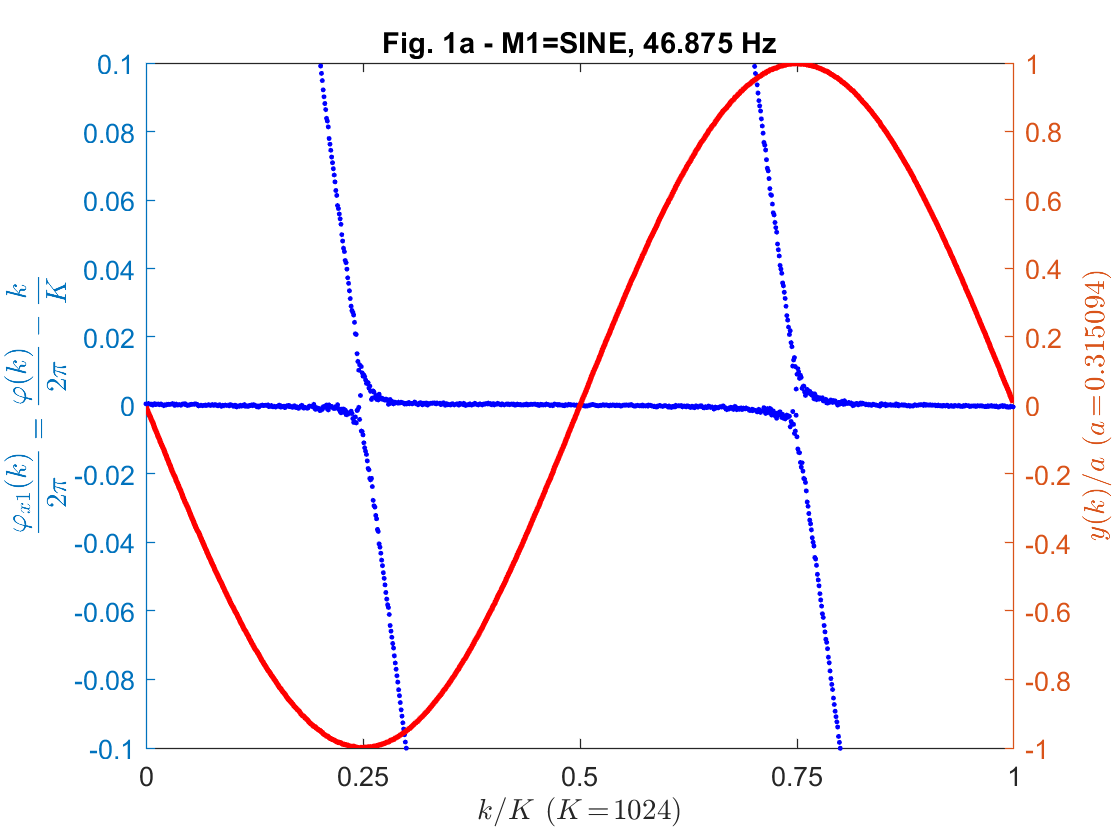

   M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=00

     USING PRE-COMPUTED PLOT DATA from ../waves/recordings/phase modulation measurement/plotdata/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=00.mat

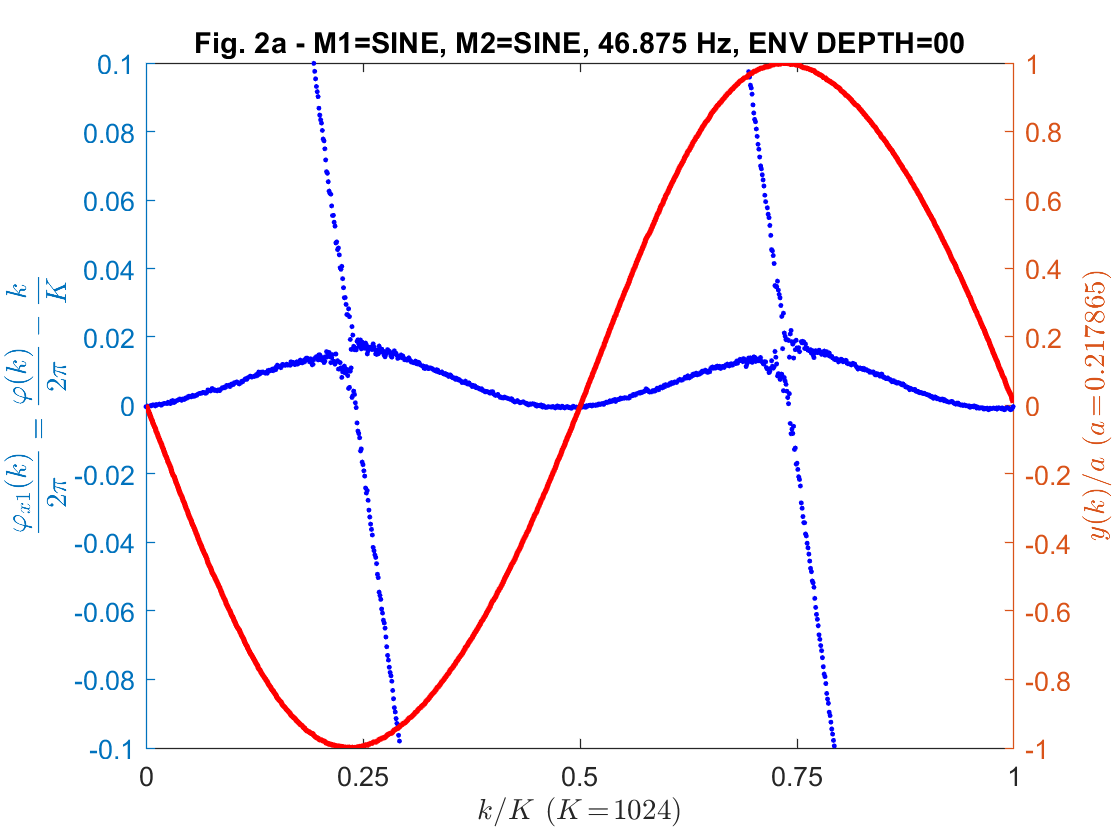

   M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=09

     USING PRE-COMPUTED PLOT DATA from ../waves/recordings/phase modulation measurement/plotdata/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=09.mat

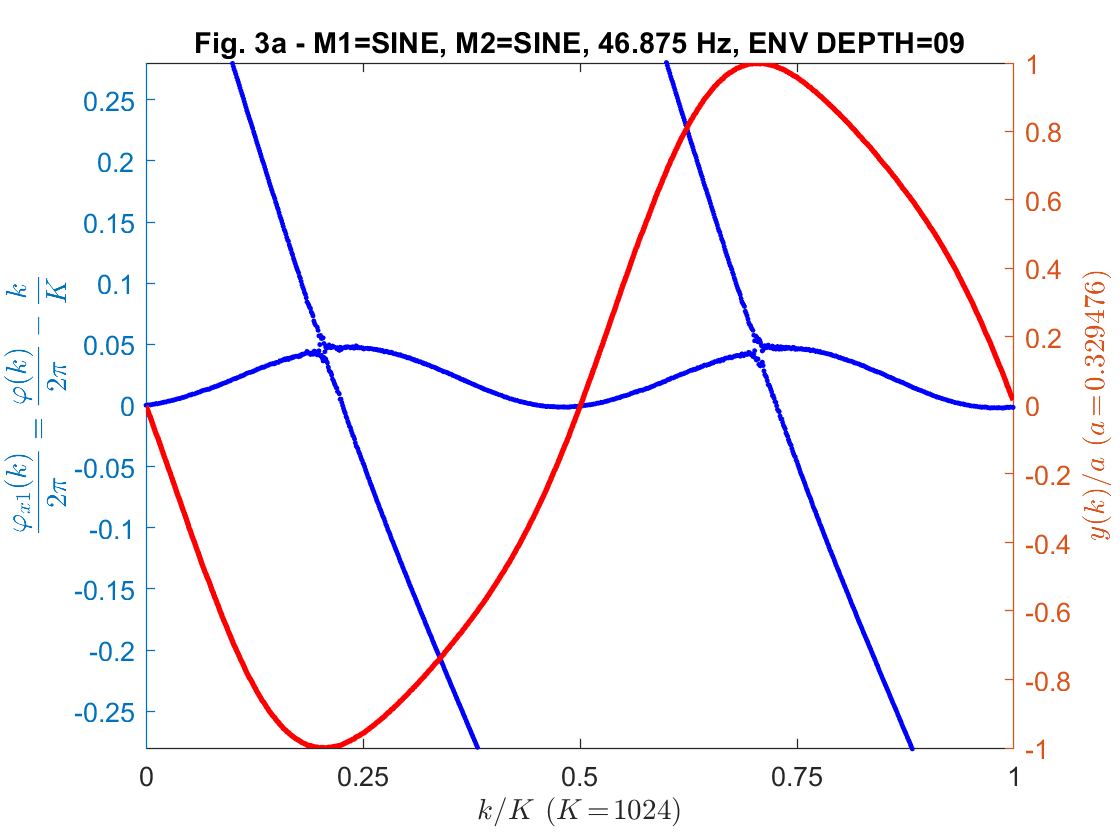

   M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=19

     USING PRE-COMPUTED PLOT DATA from ../waves/recordings/phase modulation measurement/plotdata/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=19.mat

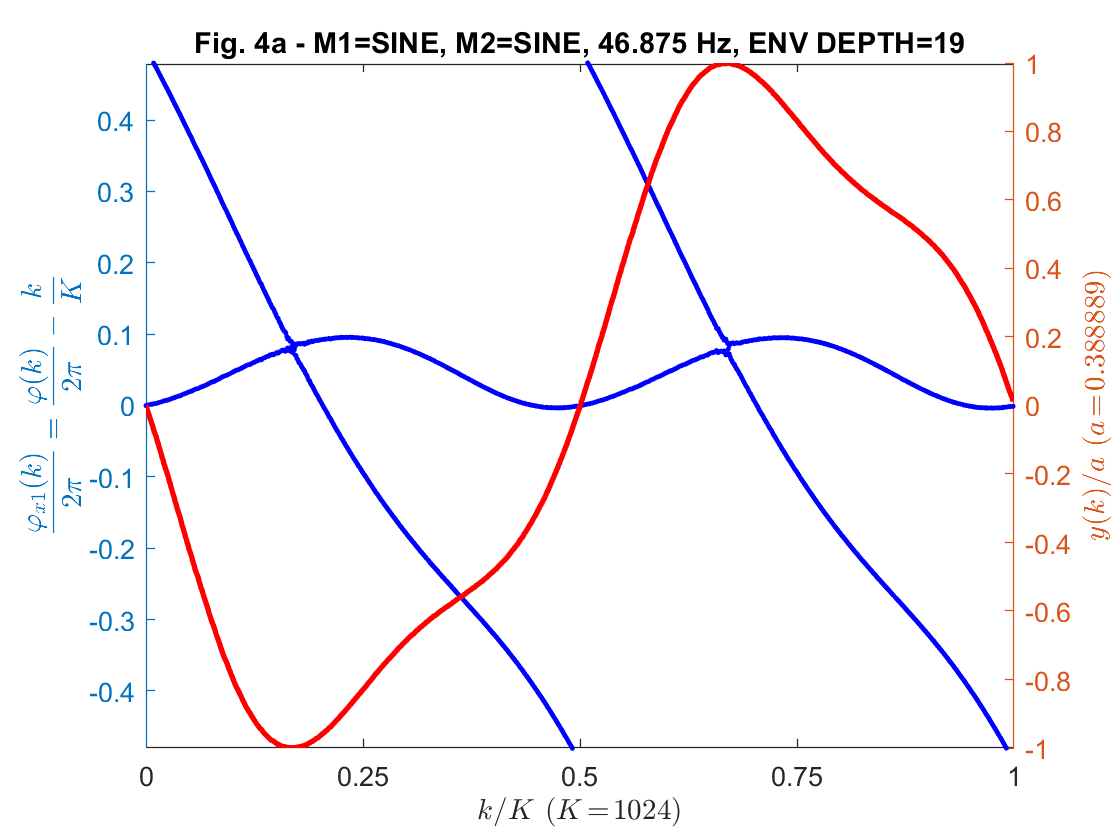

   M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=29

     USING PRE-COMPUTED PLOT DATA from ../waves/recordings/phase modulation measurement/plotdata/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=29.mat

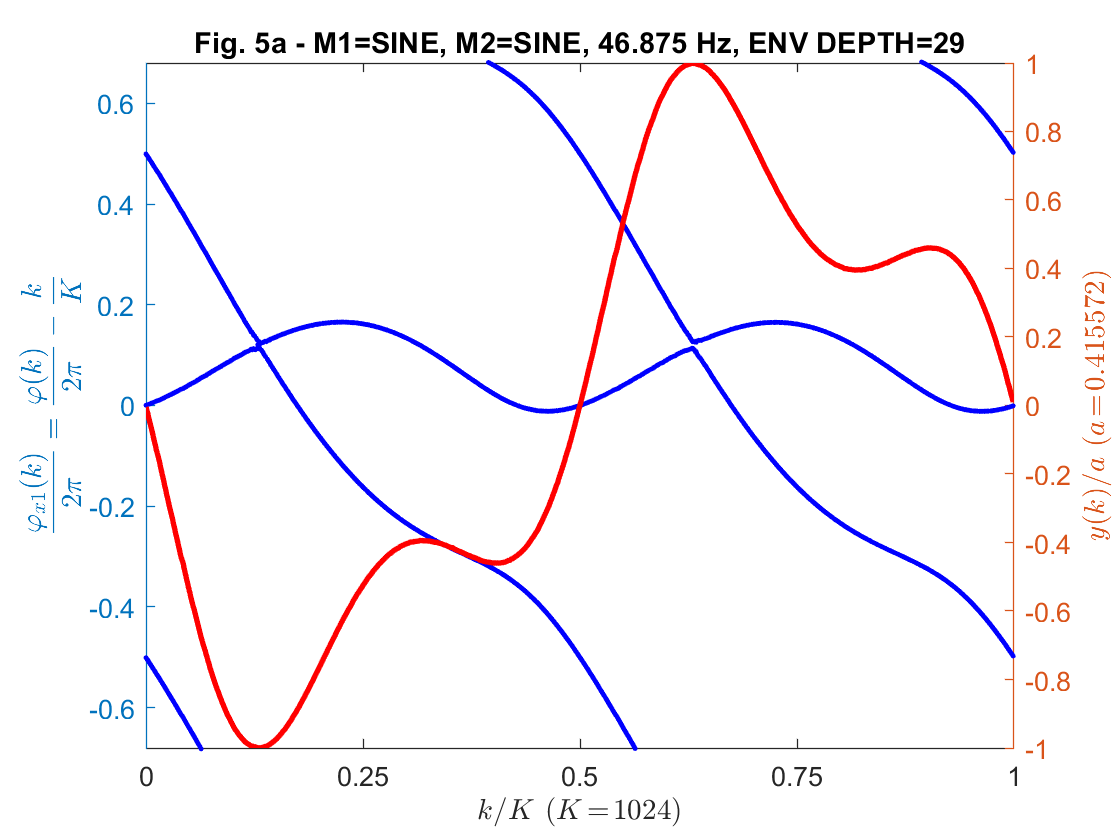

   M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=39

     USING PRE-COMPUTED PLOT DATA from ../waves/recordings/phase modulation measurement/plotdata/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=39.mat

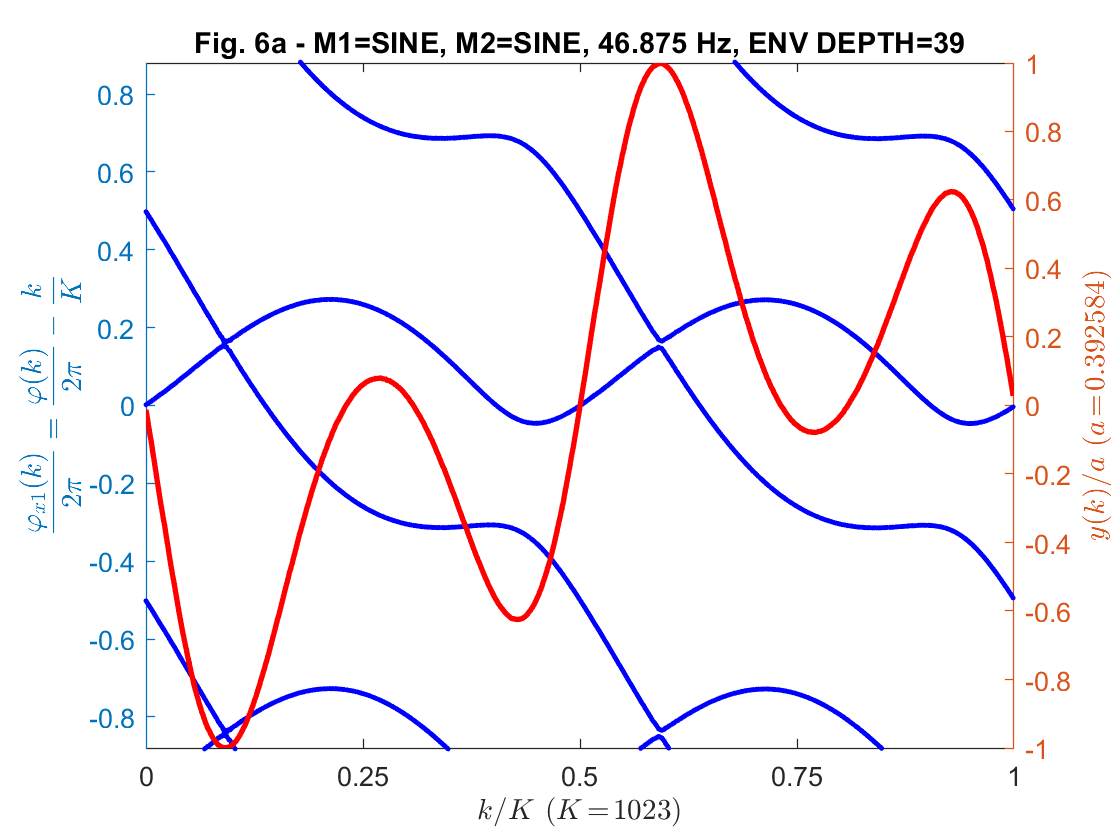

   M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=49

     USING PRE-COMPUTED PLOT DATA from ../waves/recordings/phase modulation measurement/plotdata/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=49.mat

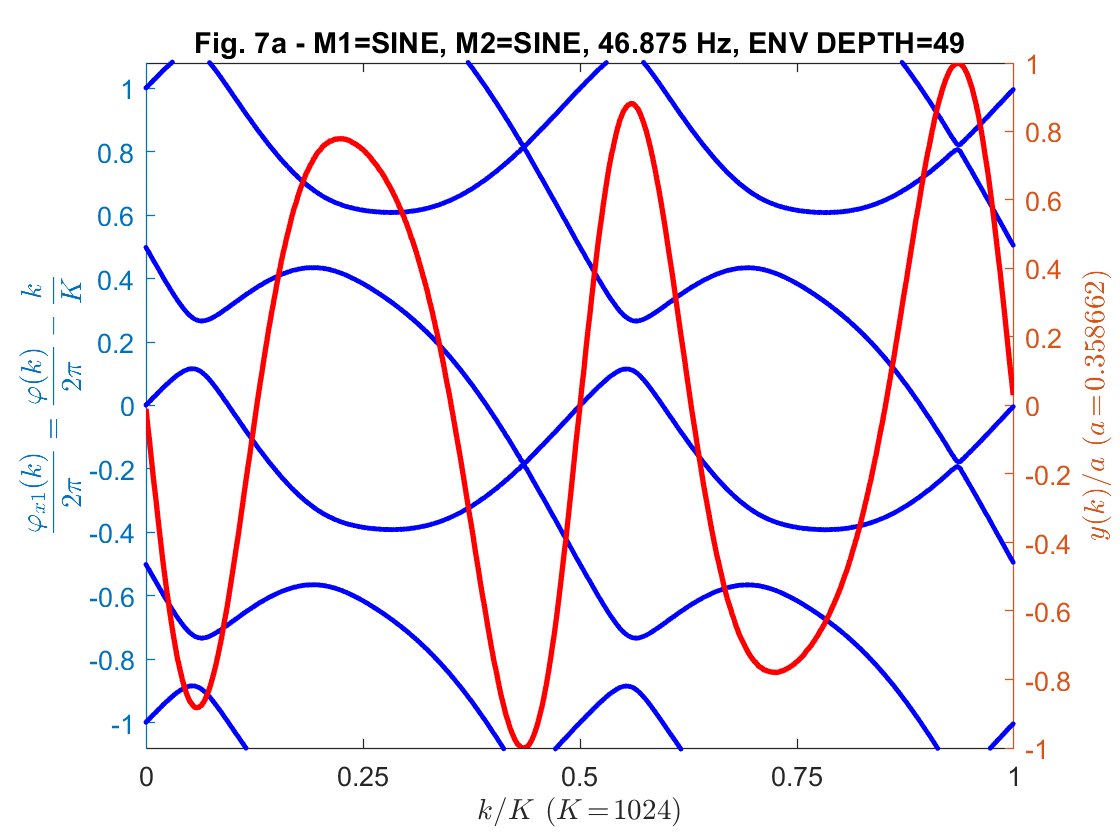

   M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=59

     USING PRE-COMPUTED PLOT DATA from ../waves/recordings/phase modulation measurement/plotdata/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=59.mat

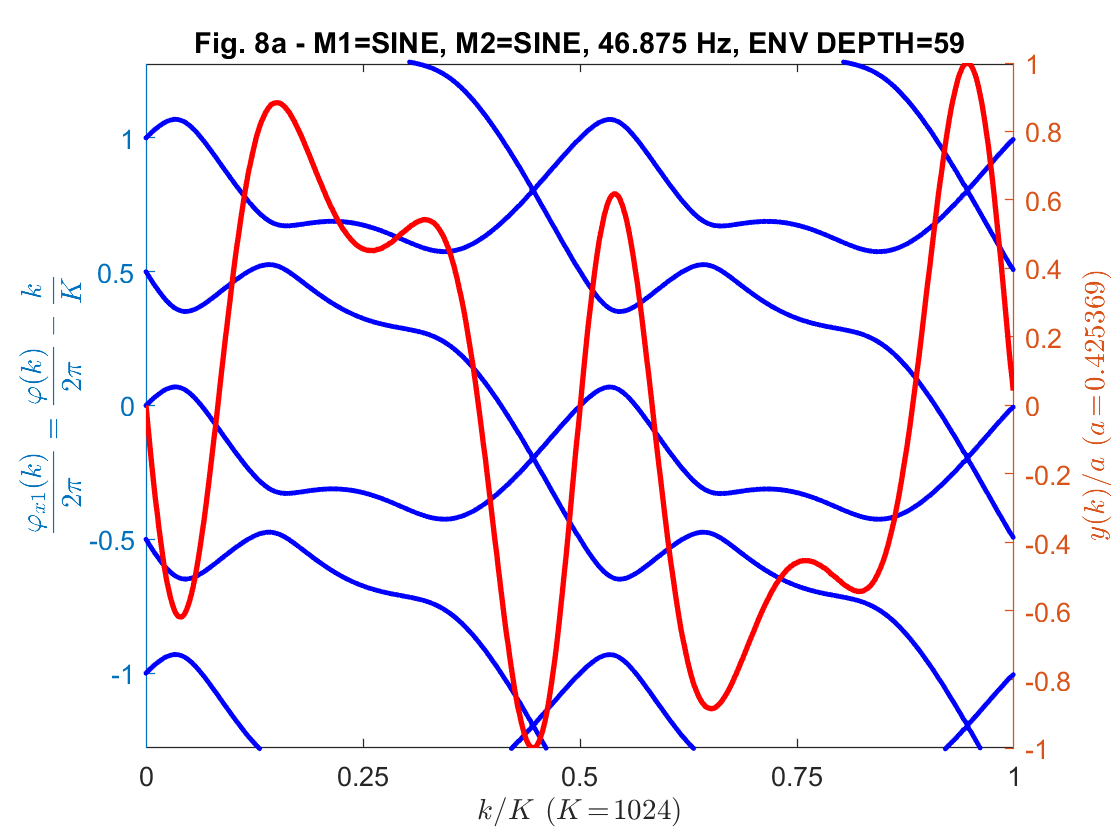

   M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=69

     USING PRE-COMPUTED PLOT DATA from ../waves/recordings/phase modulation measurement/plotdata/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=69.mat

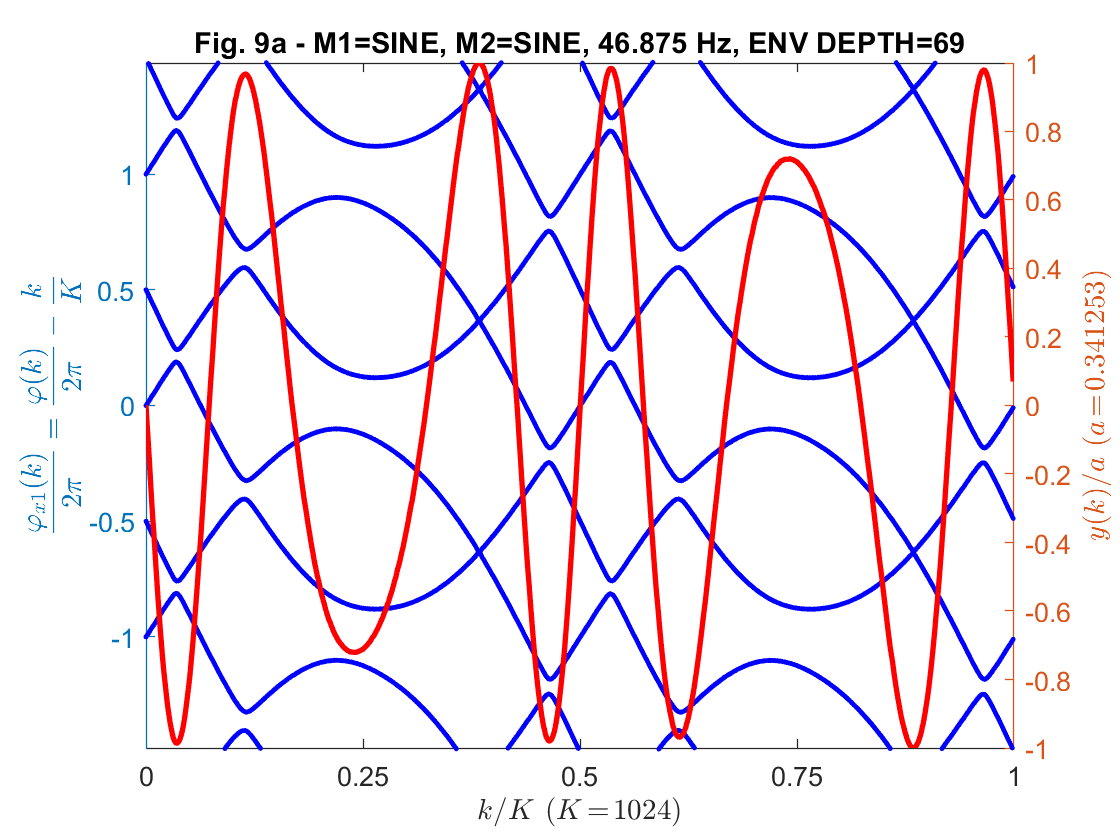

   M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=79

     USING PRE-COMPUTED PLOT DATA from ../waves/recordings/phase modulation measurement/plotdata/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=79.mat

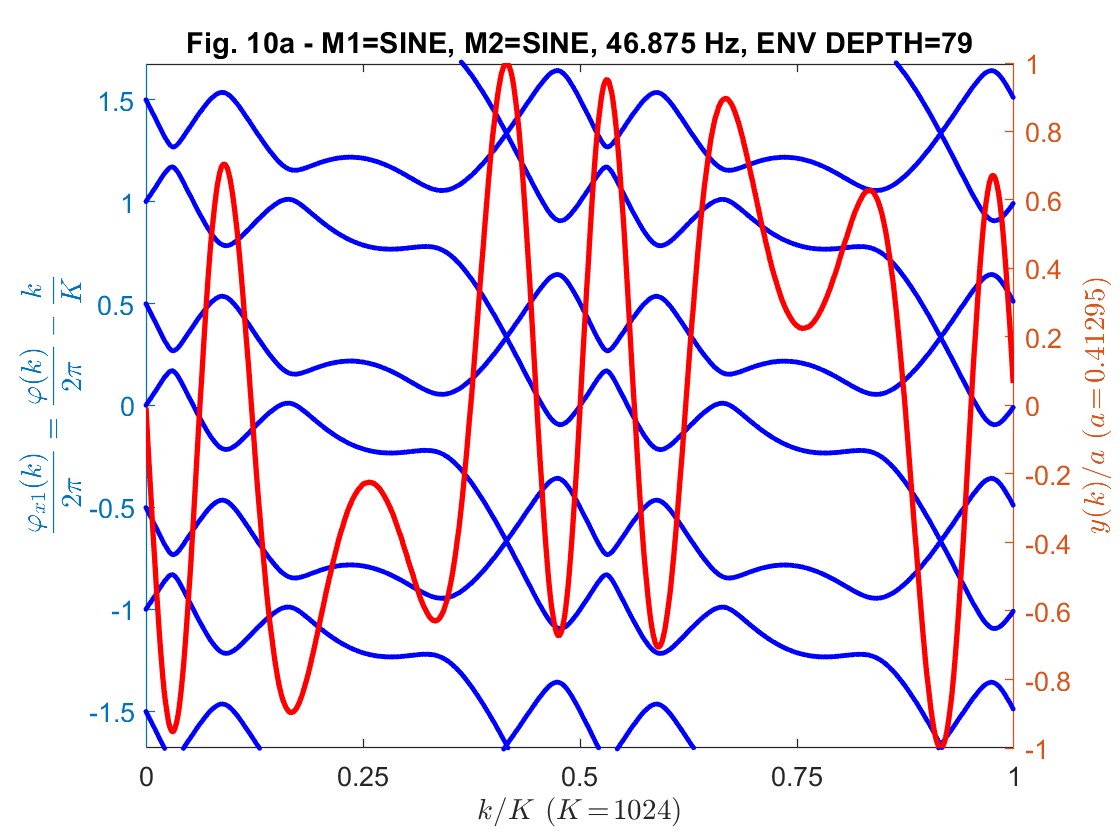

   M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=89

     USING PRE-COMPUTED PLOT DATA from ../waves/recordings/phase modulation measurement/plotdata/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=89.mat

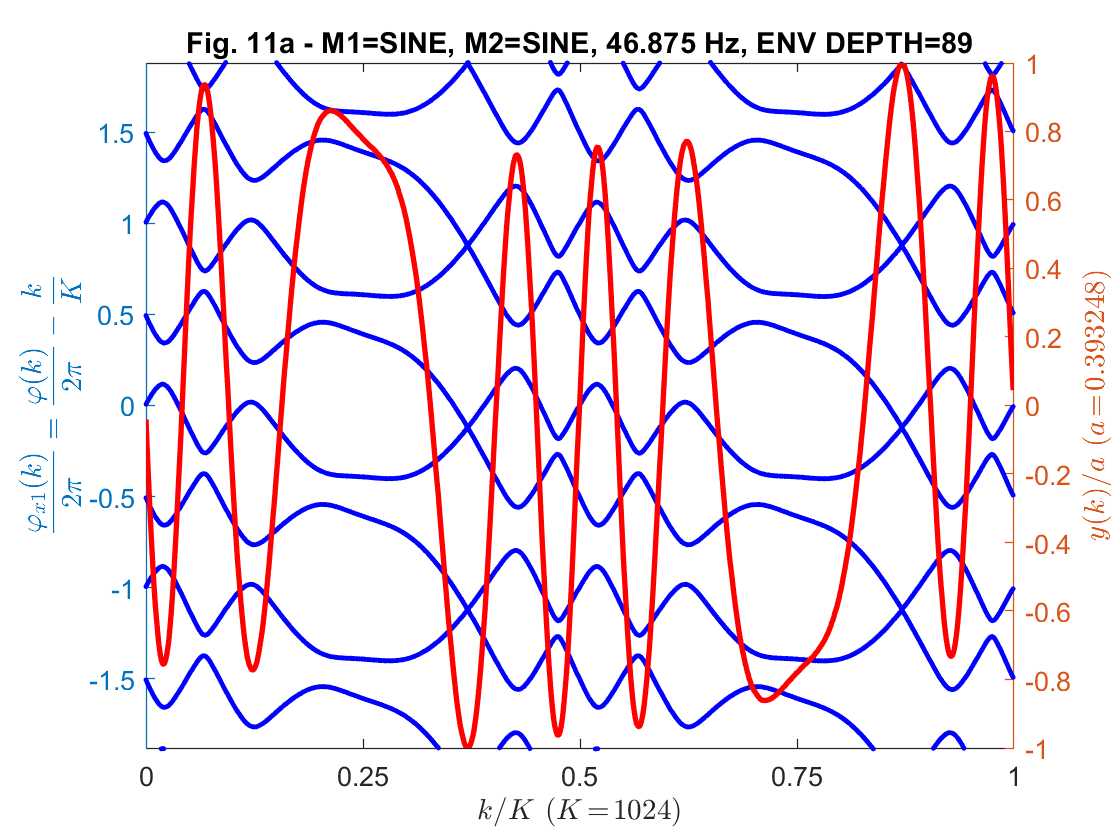

   M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=99

     USING PRE-COMPUTED PLOT DATA from ../waves/recordings/phase modulation measurement/plotdata/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=99.mat

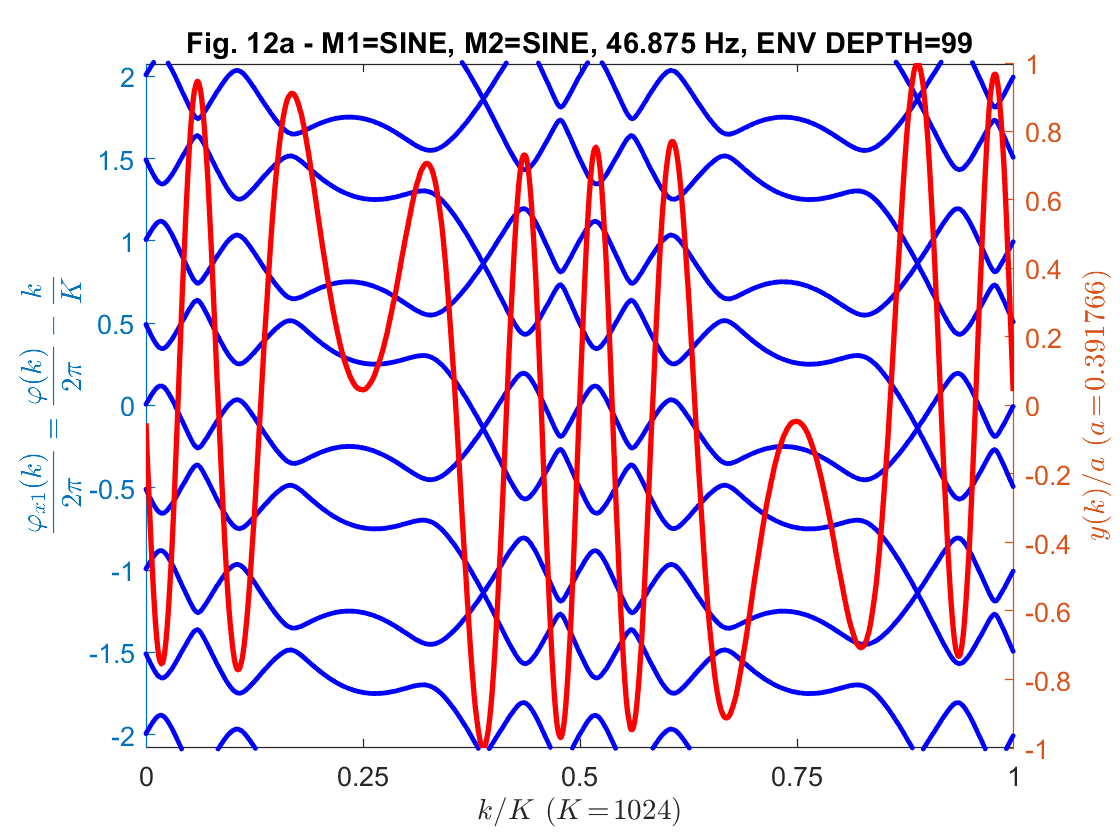

syms p real;
assume(p>0 & p<=2*pi);

for i=1:12
  fprintf('   %s',name(i));
  analyzeSinePhase(name(i),wave{i},a(i),h(i),dirPlotData,forceRecompute,...
    sprintf("%da",i));
end

The first plot is a single unmodulated sine just for testing the solver. Plots 2 through 6 (`ENV DEPTH` $\in$ [ `00`, `09`, `19`, `29`, `39` ]) indicate, that $x_2$ might be phase-modulated with the *square* of $x_1$:

    $y(t) = a\cdot \sin\big(2\pi f_0t + 2\pi\,h\,\sin^2(2\pi f_0 t-\pi)\big)$.

I observe that 

- already at `ENV DEPTH=00` there seems to be some modulation,

- the squared sine---if it is a squared sine---exposes little phase and amplitude offsets.

The remaining plots are just a big mess; probably due to phase wrapping... :(

Let's test the square hypothesis. I first read the positions $k_{2\max}$, $k_{2\min}$ and values $\varphi_{2\max}$, $\varphi_{2\min}$ of first maximum and the last minimum the (blue) "squared sines". Then I model the phase function $\varphi_{x1}$ by

    $\varphi_{x1,\text{ MODEL}}(k)=2\pi\,\varphi_{2\max}\,\sin^2\left(2\pi\frac{k}{K}-\pi\right)$      for $0\leq k< K$,

and plot the locations of the maxima, the model phase function and the original phase function.

fprintf(['_____________________________________________________________________\n' ...
 'Test Model']);

_____________________________________________________________________
Test Model

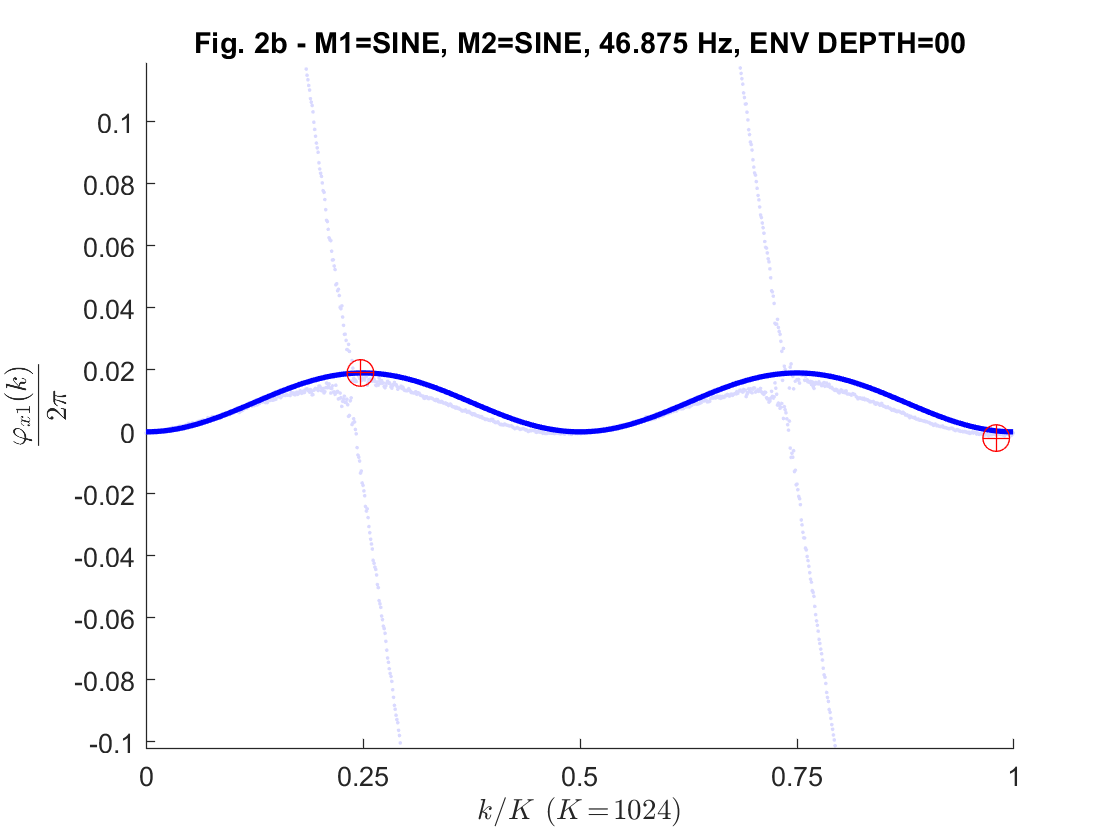

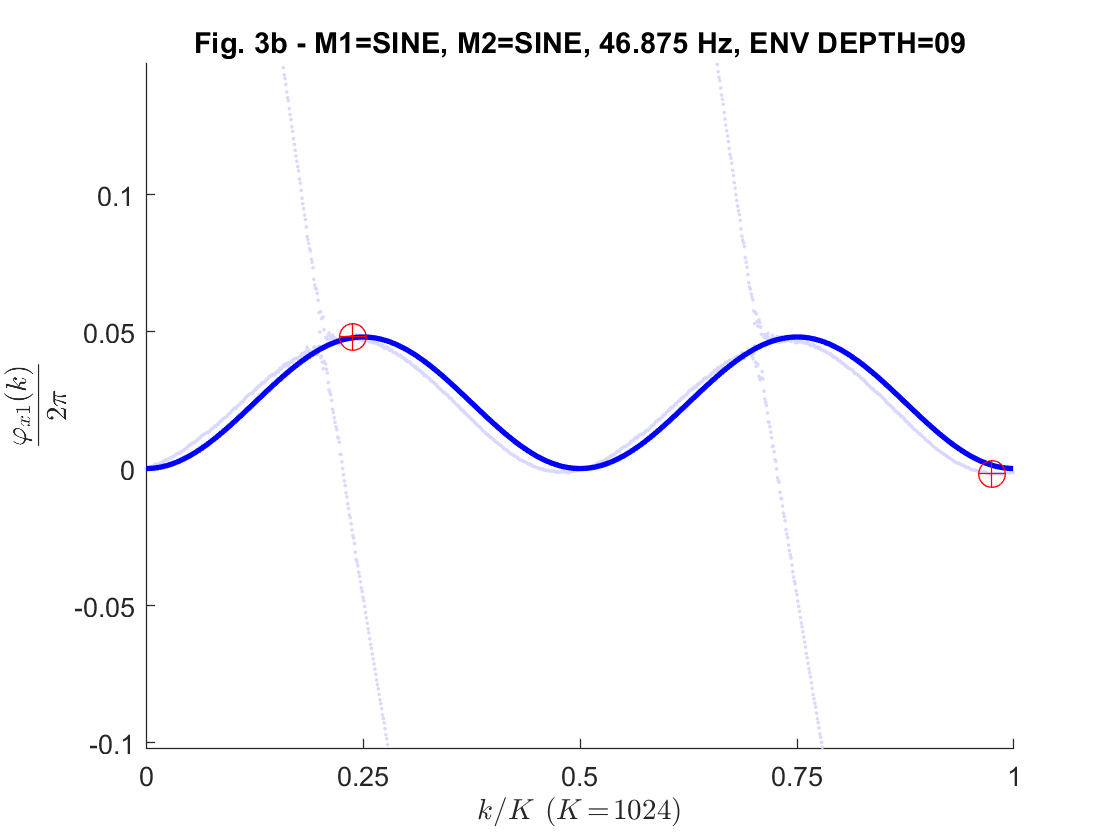

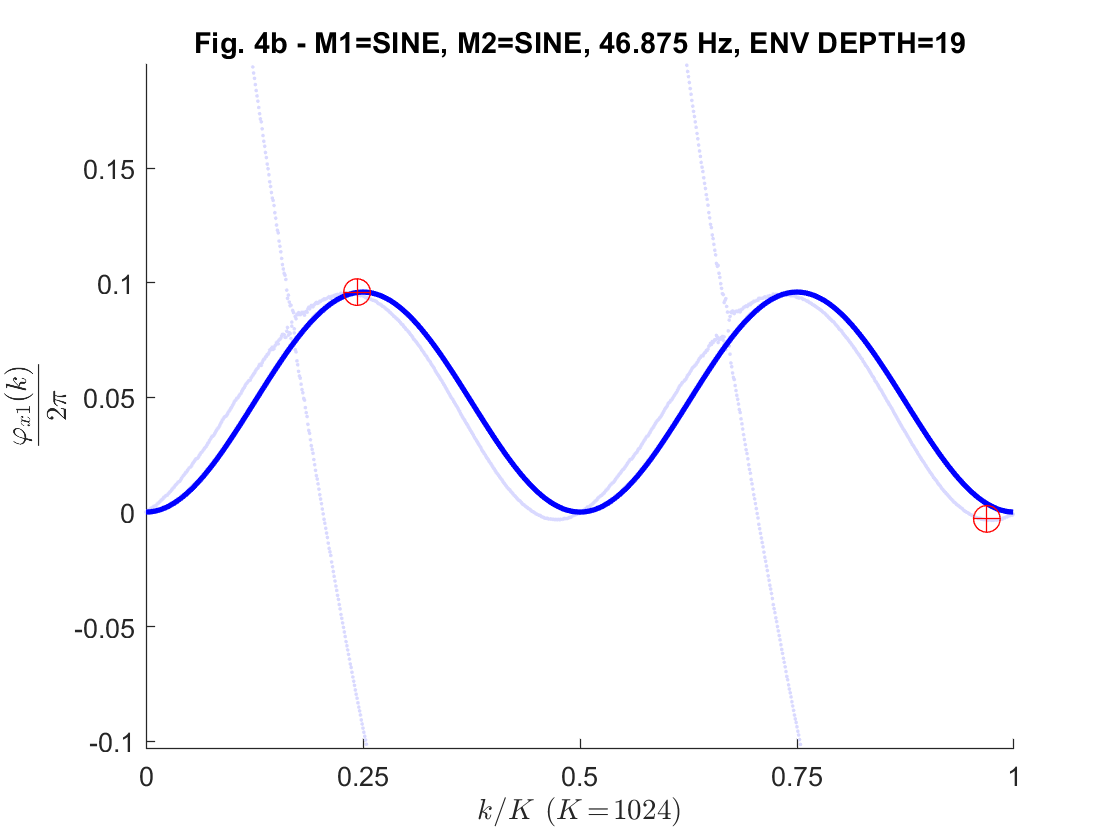

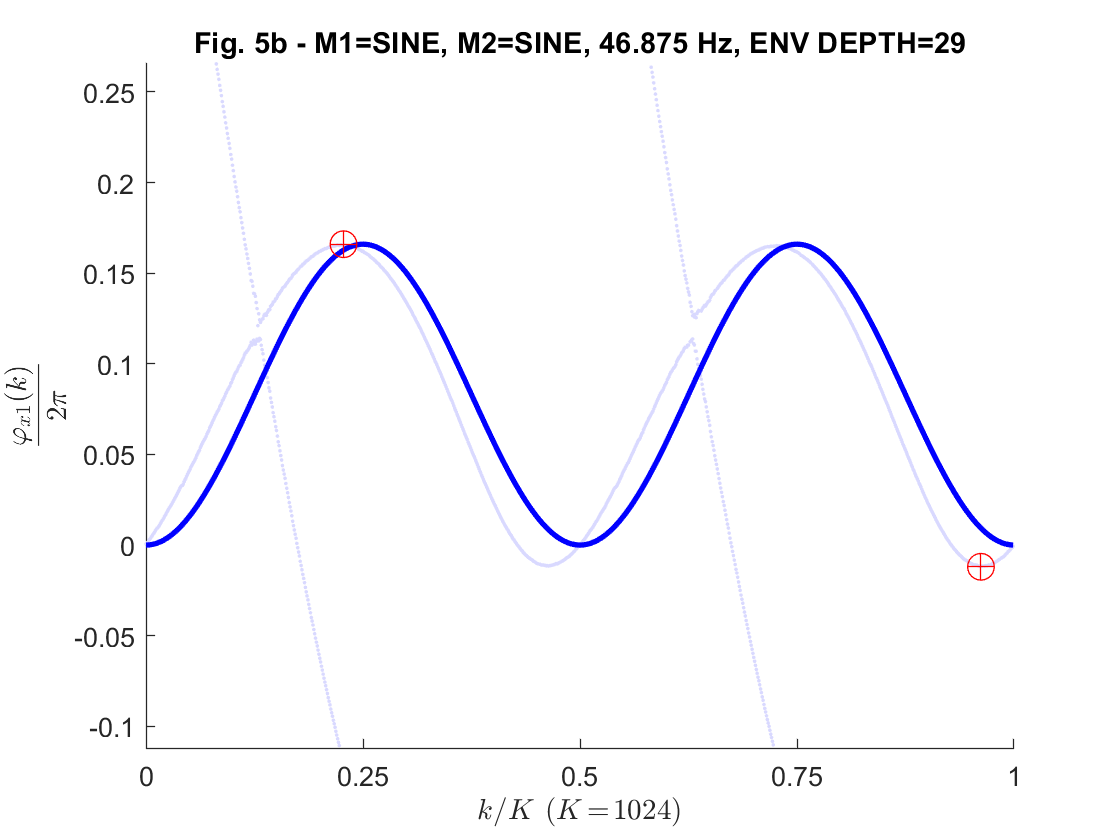

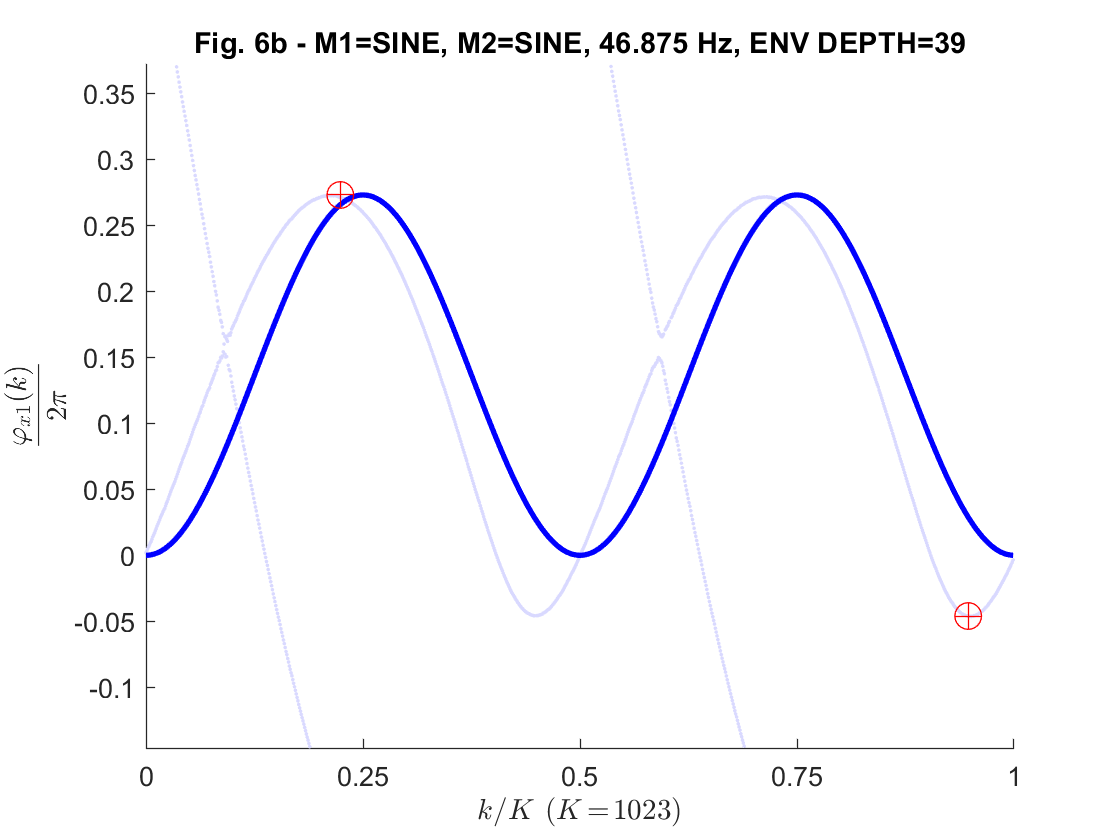

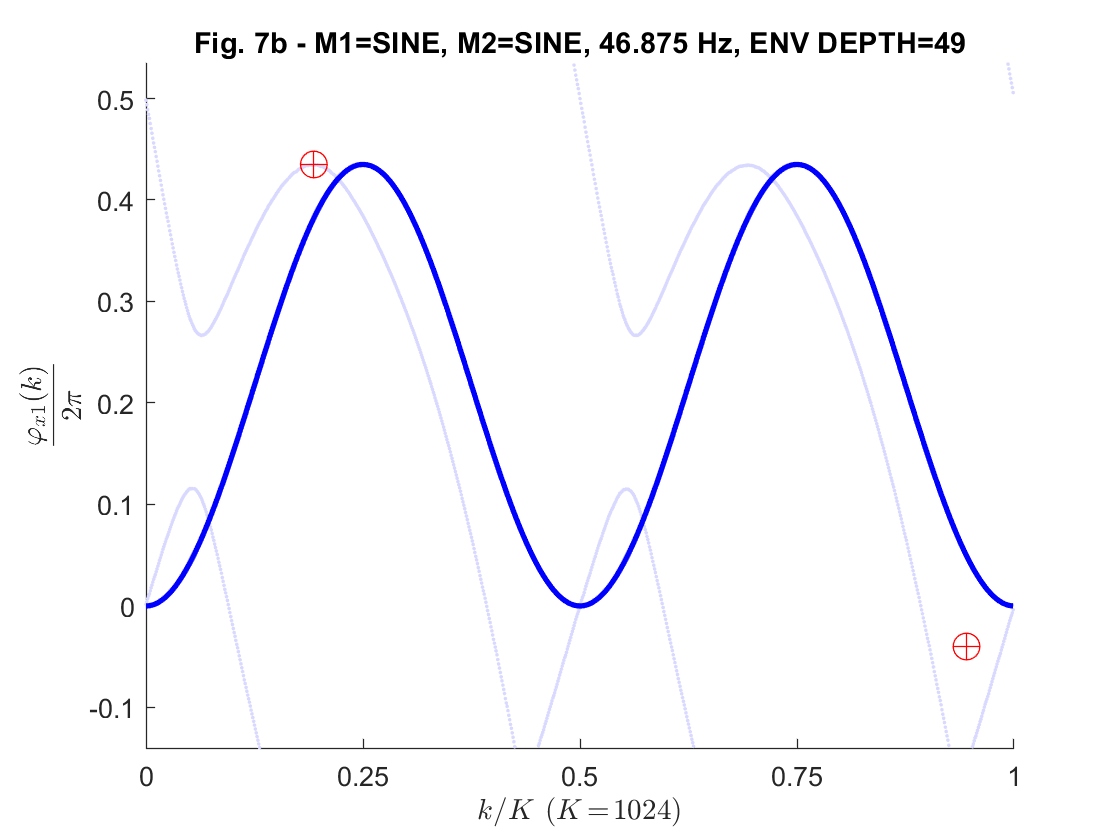

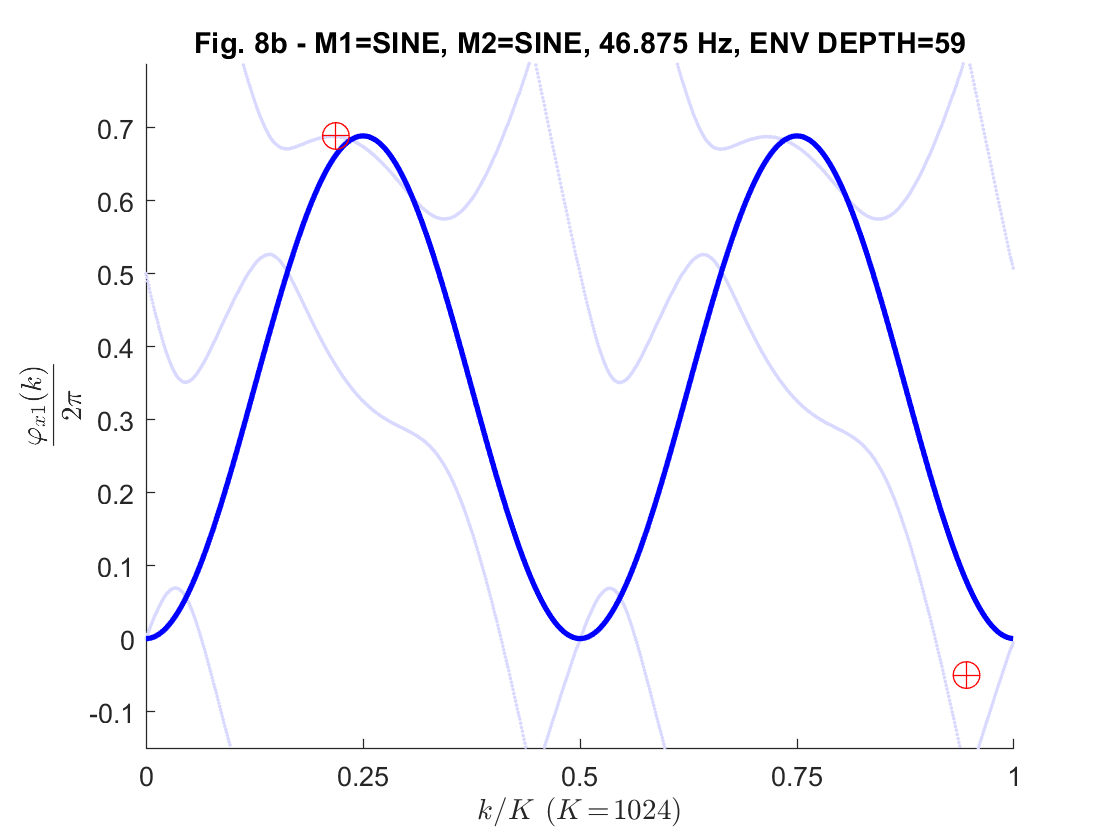

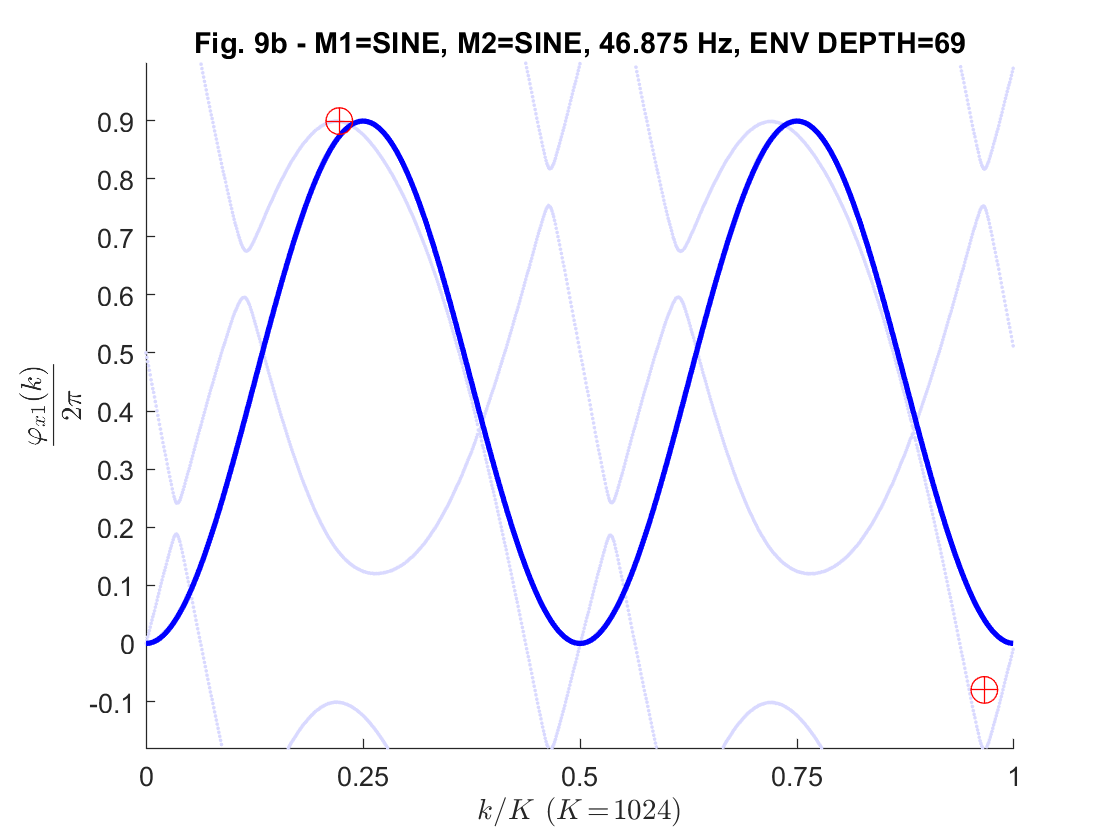


% ENV DEPTH:    00     09     19     29     39     49     59     69     79     89     99
phi2max =  [ 0.019; 0.048; 0.096; 0.166; 0.273; 0.435; 0.689; 0.899; 1.218; 1.5  ; 1.75 ];
k2max   =  [   253;   244;   249;   233;   229;   198;   224;   228;   243;   246;   245];
phi2min =  [-0.002;-0.002;-0.003;-0.012;-0.046;-0.04 ;-0.05 ;-0.08 ;-0.09 ;-0.10 ; -0.10];
k2min   =  [  1003;   998;   992;   985;   969;   968;   968;   989;  1001;   998;  1001];

C = 2;
for i=1:11
  figure;
  fnPlotData = dirPlotData+name(i+1)+".mat";
  load(fnPlotData,'phi');
  K = length(phi);
  X = zeros(0,0);
  Y = zeros(0,0);
  for k=0:K-1
    X = [X; ones(length(phi{k+1})*(2*C+1),1)*k];
    for j=-C:C; Y = [Y; (phi{k+1}+j*2*pi)/2/pi-k/K]; end
  end
  scatter(X,Y,2,'filled','MarkerFaceColor',[0.85 0.85 1]);
  ylim([phi2min(i)-0.1 phi2max(i)+0.1]);
  xlim([0 K]);
  set(gca,'XTick',0:K/4:K);
  set(gca,'XTickLabel',{'0','0.25','0.5','0.75','1'});
  xlabel("$$k/K$$ ($$K\!=\!"+sprintf('%d',K)+"$$)",'Interpreter','latex');
  ylabel('$$\frac{\varphi_{x1}(k)}{2\pi}$$','Interpreter','latex');
  title(sprintf('Fig. %db - %s',i+1,name(i+1)));
  hold on;
  k = 0:K-1;
  plot(k,phi2max(i)*(sin(2*pi.*k/K-pi)).^2,'blue','LineWidth',2);
  scatter([k2max(i) k2min(i)],[phi2max(i) phi2min(i)],100,'+','red');
  scatter([k2max(i) k2min(i)],[phi2max(i) phi2min(i)],100,'o','red');
  hold off;
end

Finally, I simulate the phase modulated signals

    $y_{\text{MODEL}}(k) = \sin\left(2\pi \frac{k}{K}+2\pi\,\varphi_{2\max}\,\sin^2\left(2\pi\frac{k}{K}-\pi\right)-\pi\right)$   for $0\leq k<K$

and plot them together with the respective recorded waveforms $y_{\text{REC}}(k)$:

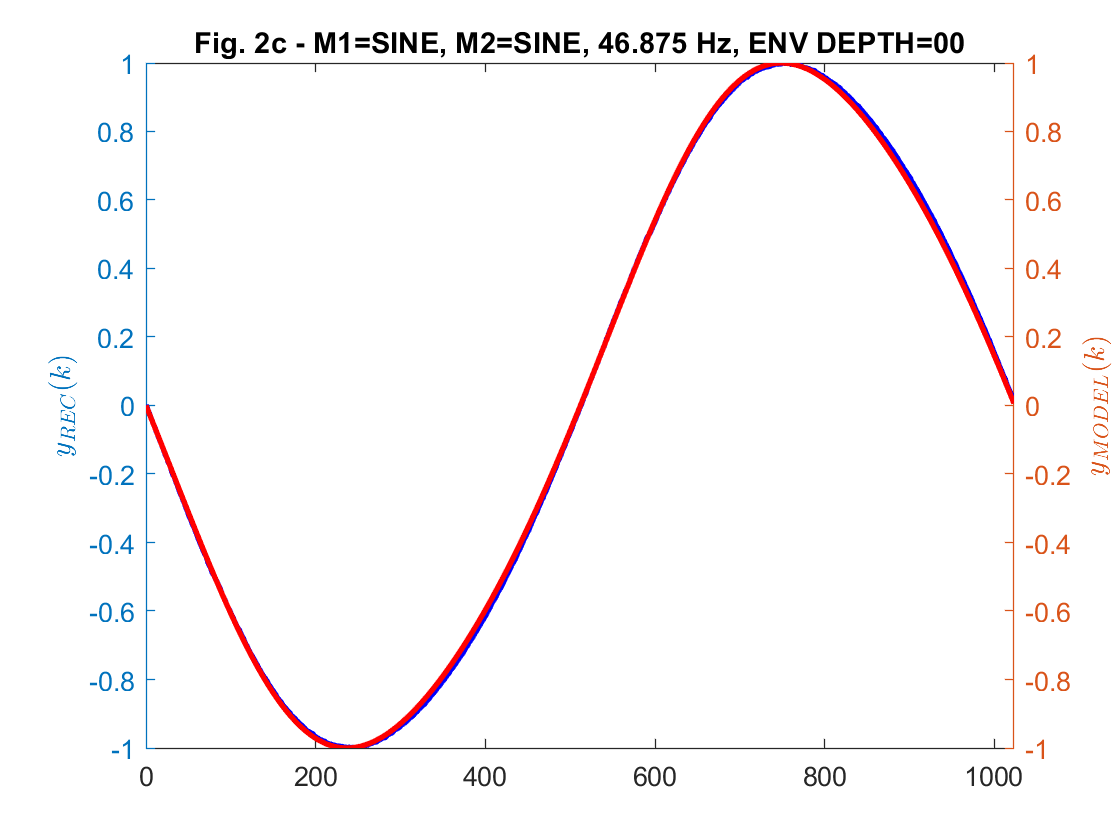

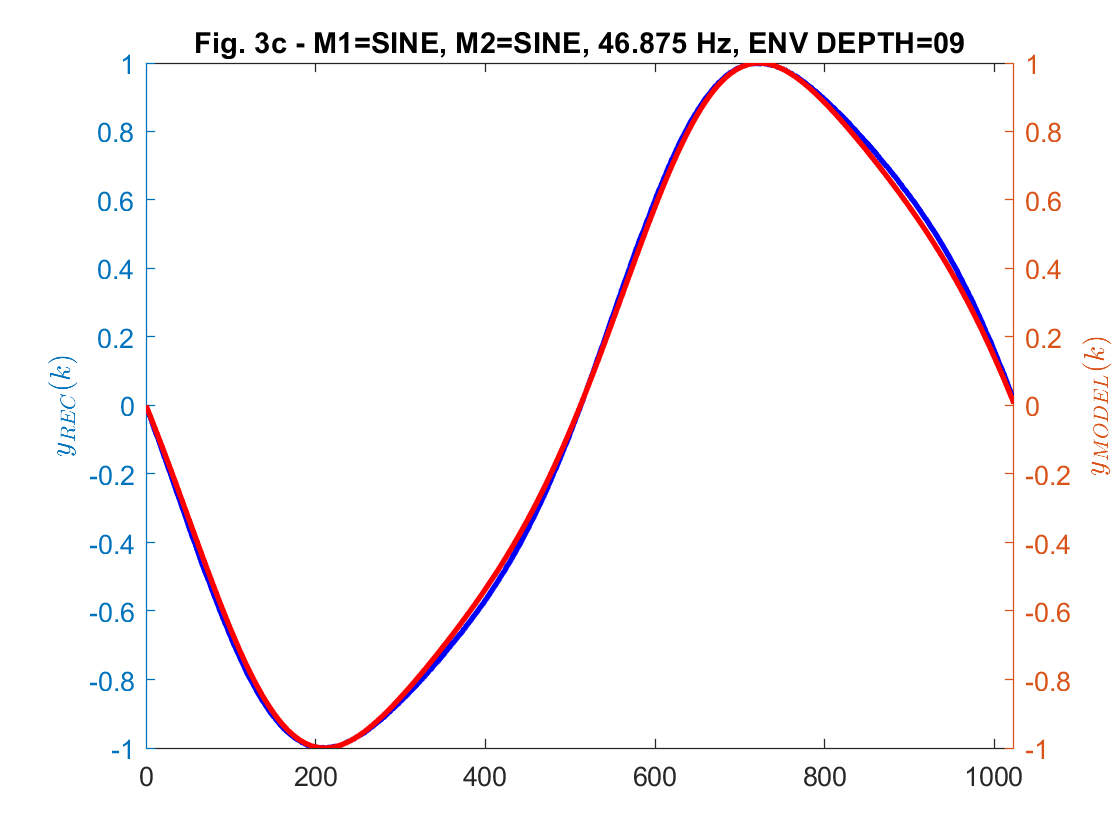

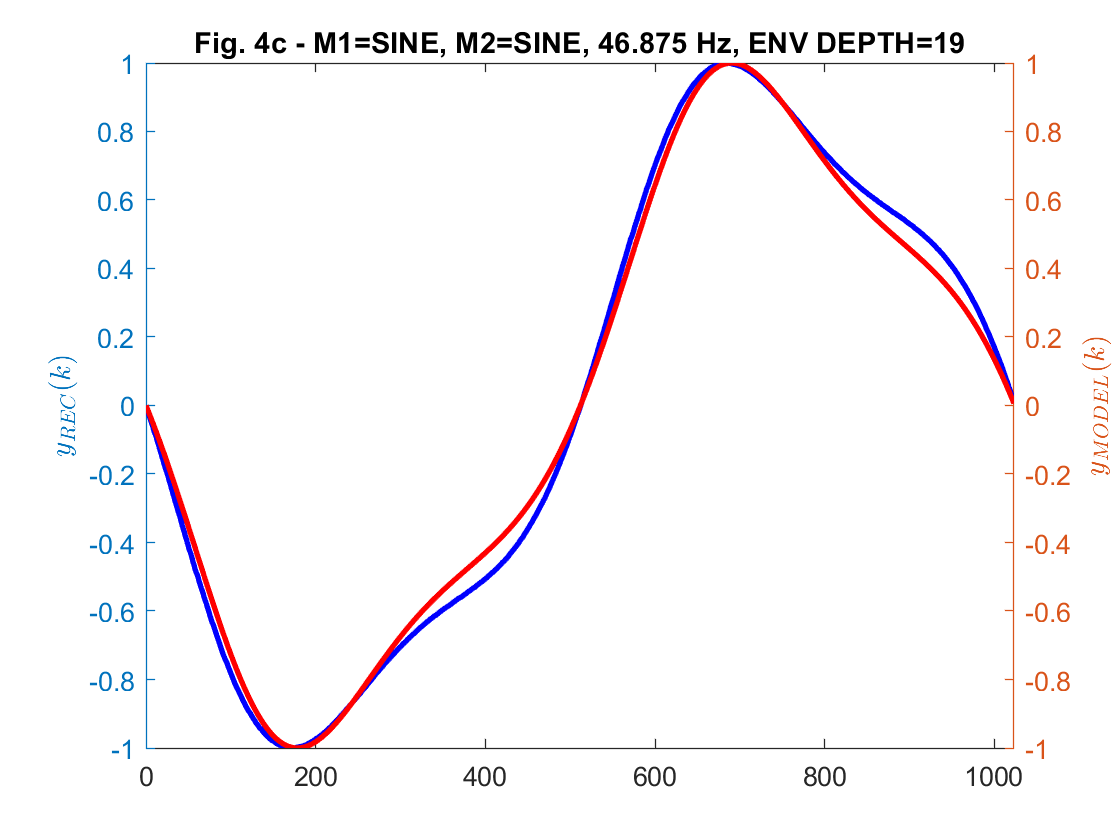

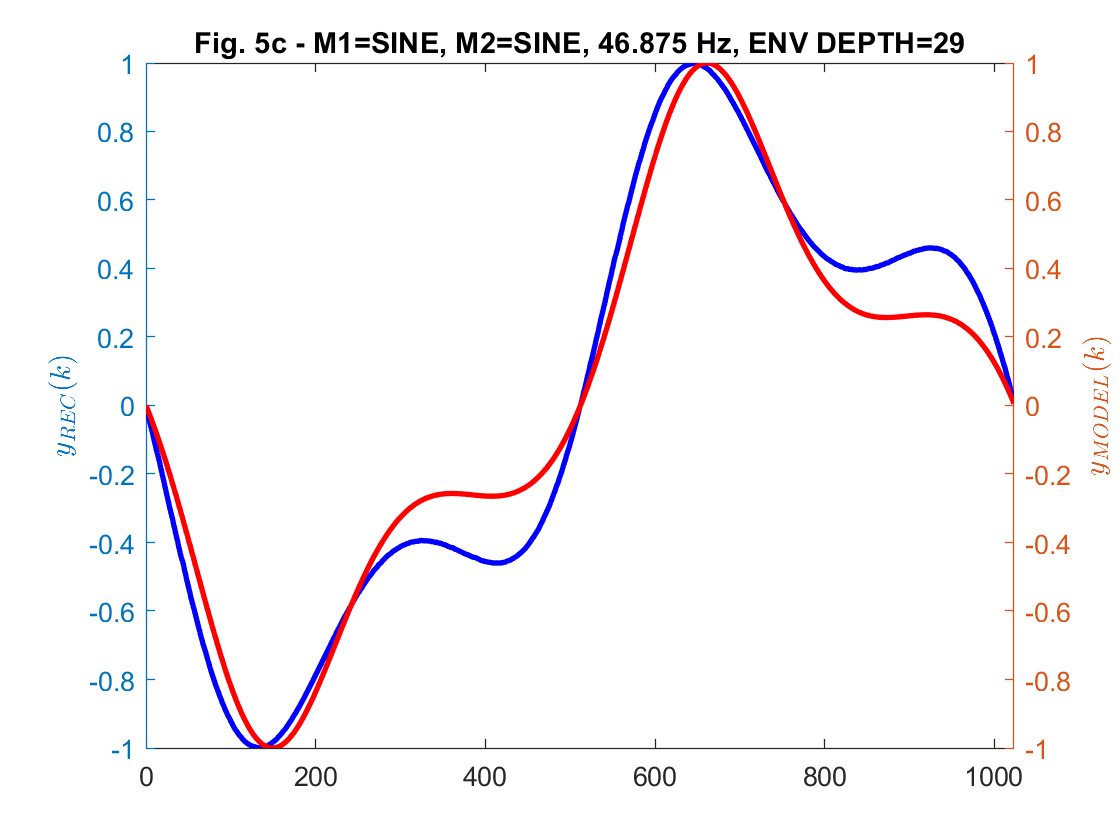

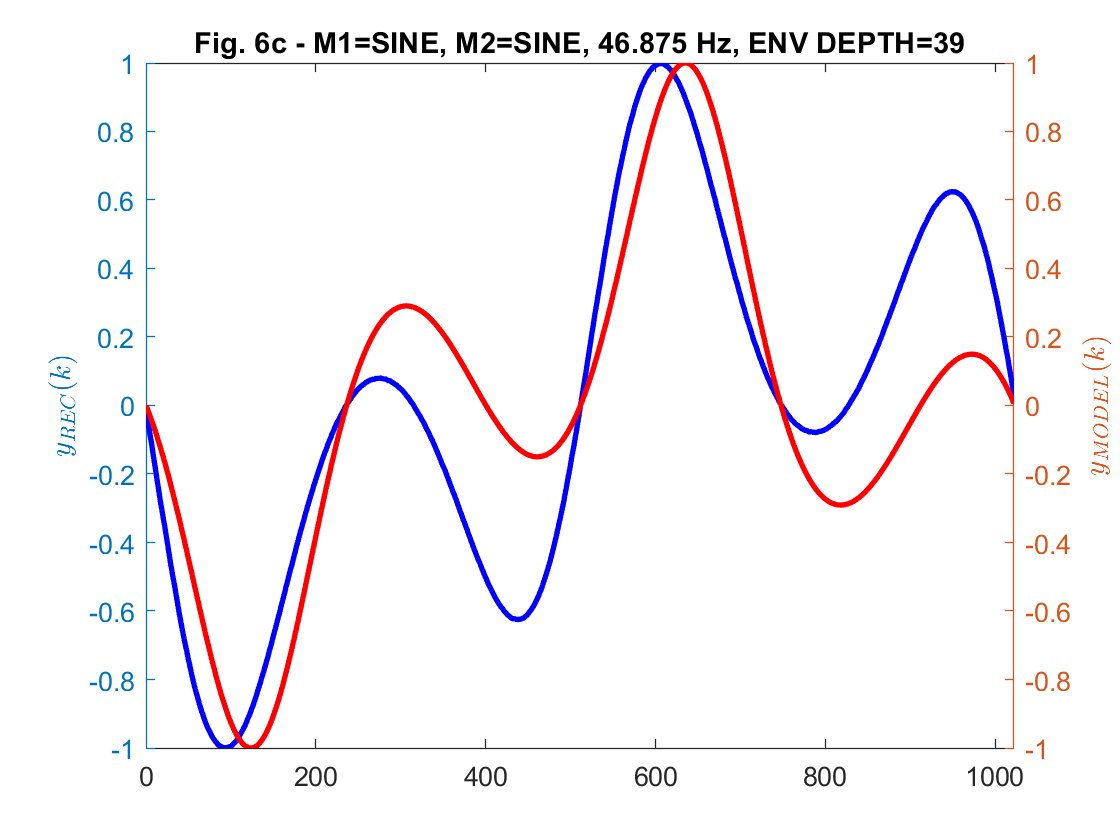

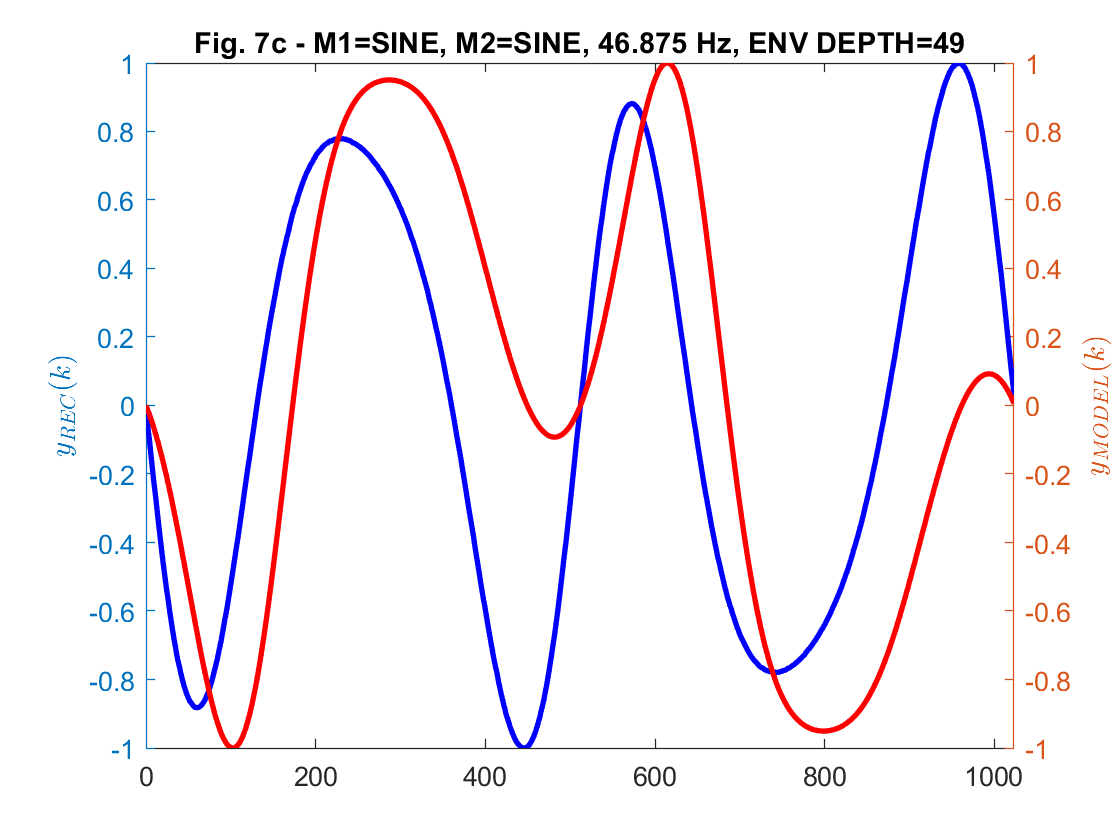

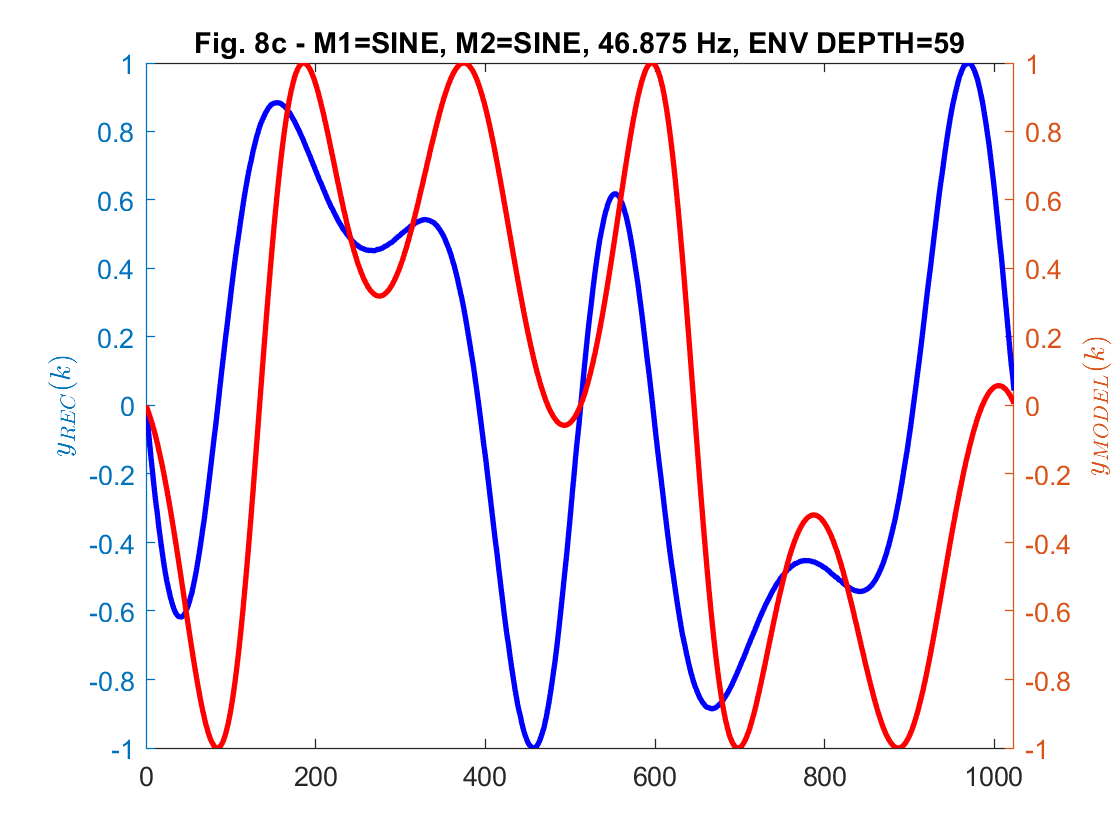

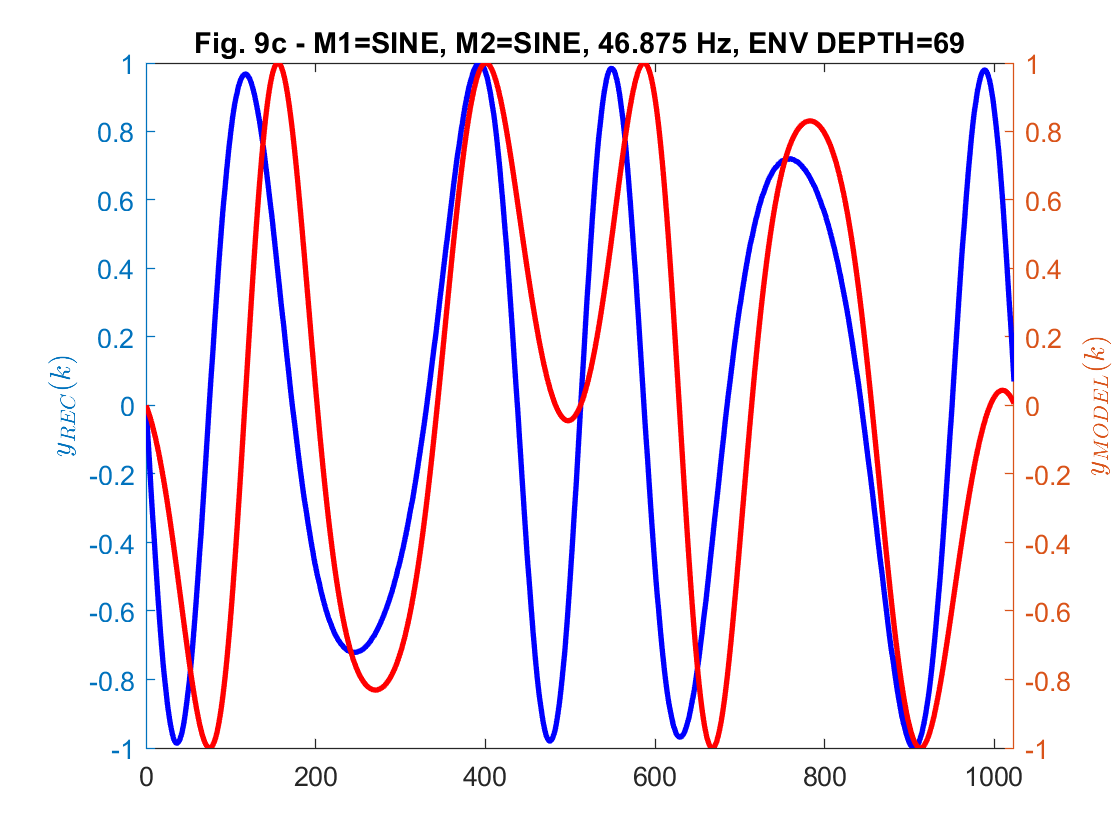

for i=1:11
  K = length(wave{i+1});
  k = 0:K-1;
  Y = sin(2*pi.*k/K + 2*pi*phi2max(i).*power(sin(2*pi.*k/K-pi),2) - pi);
  figure;
  yyaxis left;
  plot(k,wave{i+1}./a(i+1),'LineWidth',2,'Color','blue');
  hold on;
  ylabel('$$y_{REC}(k)$$','Interpreter','latex');
  yyaxis right;
  plot(k,Y,'LineWidth',2,'Color','red');
  ylabel("$$y_{MODEL}(k)$$",'Interpreter','latex');
  title(sprintf('Fig. %dc - %s',i+1,name(i+1)));
  xlim([0,K-1]);
end

Well, I've seen nicer fits. But results are not too bad after all...

**[TODO:** Plot $\varphi_{2\max}$ against `ENV DEPTH`!**]**

### 2.3   `SAWn` v. `SINE` Phase Modulation

**[TODO:** ...**]**

## 3   Conclusion

**[TODO:** ...**]**

Tuned into:

- Sandra: Paintings in Yellow

- Depeche Mode: Playing the Angel

## **Appendix A   Local Functions**

### **A.1   Sine Phase Modulation Analysis**

function analyzeSinePhase(name,wave,a,h,dirPlotData,forceRecompute,figNo)
  % Computes the phase modulation angle of a sine cycle given a modulated
  % signal.
  %
  %    analyzeSinePhase(name,wave,a,h,dirPlotData,forceRecompute,figNo)
  %
  % arguments:
  %    name           - name of modulated signal (and file name!)
  %    wave           - modulated signal (exactly one cycle!)
  %    a              - amplitude of modulated signal (for normalization)
  %    h              - approximate modulation index (used for plot scaling only)
  %    dirPlotData    - pre-computed plot data folder
  %    forceRecompute - recompute analysis (instead of read result from data file)
  %    figNo          - figure number for plot, e.g., "10a"
    
  K = length(wave);
  C = 3; % Phase unwrapping cycles

  % Downsample ->
  %wav = interp1(1:K,wav,1:10:K);
  %K   = length(wav);
  % <--

  phi = cell(1,K);
  figure;
  yyaxis right;
  plot(0:K-1,wave./a,'LineWidth',2,'Color','red'); hold on;
  title(sprintf('Fig. %s - %s',figNo,name));
  xlim([0 K]);
  set(gca,'XTick',0:K/4:K);
  set(gca,'XTickLabel',{'0','0.25','0.5','0.75','1'});
  xlabel("$$k/K$$ ($$K\!=\!"+sprintf('%d',K)+"$$)",'Interpreter','latex');
  ylabel("$$y(k)/a$$ ($$a\!=\!"+sprintf('%g',a)+"$$)",'Interpreter','latex');
  yyaxis left;
  ylabel('$$\frac{\varphi_{x1}(k)}{2\pi}=\frac{\varphi(k)}{2\pi}-\frac{k}{K}$$','Interpreter','latex');
  ylim([-2*h-0.1 2*h+0.1]);
  drawnow;
  fnPlotData = dirPlotData+name+".mat";
  recompute = true;
  if ~forceRecompute
    try
      load(fnPlotData,'phi');
      recompute = length(phi)~=K;
    catch ME
      % Ignore
    end
  end
  if recompute
    for k=0:K-1
      S = solve(wave(k+1)==a*sin(p-pi),p);
      phi{k+1} = eval(S);
      scatter(ones(length(phi{k+1}),1)*k,phi{k+1}/2/pi-k/K,2,'filled','MarkerFaceColor','blue','MarkerEdgeColor','blue');
      % raw phi(k); TODO: put on third y axis (see: https://www.mathworks.com/matlabcentral/fileexchange/4425-ploty4-m) -->
      % scatter(ones(length(phi{k+1}),1)*k,(phi{k+1})/pi,2, 'filled','MarkerFaceColor','black','MarkerEdgeColor','black');
      % <--
      drawnow; hold on;
    end
    save(fnPlotData,'phi');
  else
    fprintf("     USING PRE-COMPUTED PLOT DATA from "+fnPlotData);
    X = zeros(0,0);
    Y = zeros(0,0);
    for k=0:K-1
      X = [X; ones(length(phi{k+1})*(2*C+1),1)*k];
      for j=-C:C; Y = [Y; (phi{k+1}+j*2*pi)/2/pi-k/K]; end
    end
    scatter(X,Y,2,'filled','MarkerFaceColor','blue','MarkerEdgeColor','blue');
  end
  hold off;
  
end